# Symbolic Delta Robot

clear; clc; close all;

% Parameter from CAD
P.R = 75.488; % base center -> servo axis [mm]
P.r = 29.64; % distance to the end of each link [mm]
P.ds = 0; % offset platform joint -> joint [mm]
P.L = 57; % forearm (servo horn) length [mm]
P.l = 82; % link [mm]
P.hT = 15; % half between the two parallelogram upper[mm]
P.hB = 15; % half between the two parallelogram base[mm]
P.phi = deg2rad([-90 30 150]); % servo position around z
P.thLim = [15 170]; % usable servo range [deg]
P.m = 0.1; % assume weight of platform + load mass [kg] 
P.g = 9.81; % Gravity
P.sg = 1

P = struct with fields:
        R: 75.4880
        r: 29.6400
       ds: 0
        L: 57
        l: 82
       hT: 15
       hB: 15
      phi: [-1.5708 0.5236 2.6180]
    thLim: [15 170]
        m: 0.1000
        g: 9.8100
       sg: 1


tauStall = 1079; % MG996R N.m
recordVideo = true;
aviName = 'delta_robot_motion.avi';


## Symbolic Kinematics

syms x y z dS real
syms Rs rs Ls ls positive
syms th [3 1] real
phS = [3; 7; 11]*sym(pi)/6; % [pi/2; 7*pi/6; 11*pi/6]
d = Rs - rs; % Distance between base and moving platform
p = [x;y;z]; % End-effector position vector P
k = [0;0;1]; % Vertical unit vector k
c = sym(zeros(3,3)); dc = sym(zeros(3,3)); g =sym(zeros(3,1)); 

for i = 1:3 % Loop through each of the 3 kinematic (arm)
    u = [cos(phS(i)); sin(phS(i)); 0]; % Unit tangential vector perpendicular in XY plane
    tg = [-sin(phS(i)); cos(phS(i)); 0]; % contact direction (parallel to axis servo)
    c(:,i)  = (d + Ls*cos(th(i)))*u - Ls*sin(th(i))*k - dS*tg; % elbow shifted -(r*u + dS*t)
    dc(:,i) = Ls*(-sin(th(i))*u - cos(th(i))*k);          % dc/dtheta (use calculate Jacobian)
    g(i) = simplify((p-c(:,i)).'*(p-c(:,i)) - ls^2);   % loop constraint
end
disp('Loop constraints g_i(x,y,x, theta_i) = 0 : '); disp(g) % Equation of three symbolic

Loop constraints g_i(x,y,x, theta_i) = 0 : 


$$\begin{array}{l} \left(\begin{array}{c} {\left(\mathrm{Rs}-\mathrm{rs}-y+\mathrm{Ls}\,\cos\left({\mathrm{th}}_{1}\right)\right)}^{2}-{\mathrm{ls}}^{2}+{\left(z+\mathrm{Ls}\,\sin\left({\mathrm{th}}_{1}\right)\right)}^{2}+{\left(\mathrm{dS}-x\right)}^{2}\\ {\left(\frac{\mathrm{Rs}}{2}-\frac{\mathrm{rs}}{2}+y-\sigma_{1}+\frac{\mathrm{Ls}\,\cos\left({\mathrm{th}}_{2}\right)}{2}\right)}^{2}+{\left(\frac{\mathrm{dS}}{2}+x+\frac{\sqrt{3}\,\left(\mathrm{Rs}-\mathrm{rs}+\mathrm{Ls}\,\cos\left({\mathrm{th}}_{2}\right)\right)}{2}\right)}^{2}-{\mathrm{ls}}^{2}+{\left(z+\mathrm{Ls}\,\sin\left({\mathrm{th}}_{2}\right)\right)}^{2}\\ {\left(\frac{\mathrm{Rs}}{2}-\frac{\mathrm{rs}}{2}+y+\sigma_{1}+\frac{\mathrm{Ls}\,\cos\left({\mathrm{th}}_{3}\right)}{2}\right)}^{2}+{\left(\frac{\mathrm{dS}}{2}+x-\frac{\sqrt{3}\,\left(\mathrm{Rs}-\mathrm{rs}+\mathrm{Ls}\,\cos\left({\mathrm{th}}_{3}\right)\right)}{2}\right)}^{2}-{\mathrm{ls}}^{2}+{\left(z+\mathrm{Ls}\,\sin\left({\mathrm{th}}_{3}\right)\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\mathrm{dS}}{2} \end{array}$$

## Inverse Position kinematics : ***Ecos****θ**** + Fsin****θ**** + G = 0  (i = 1,2,3)***

thIK = sym(zeros(3,1));
for i = 1:3
    w = x*cos(phS(i)) + y * sin(phS(i)); % Radian
    wt = -x*sin(phS(i)) + y * cos(phS(i)); % Tangent
    E = 2*Ls*(d-w); % Ei = 2*L*(y + a)
    F = 2*z*Ls; % Fi = 2*z*L
    G = ((w-d)^(2) + (wt+dS)^(2)) + z^2 + Ls^2 + ls^2; % Gi = (x^2 + y^2 + 2*y*a) + z^2 +a^2 + L^2 - l^2
    thIK(i) = 2*atan2(-F + P.sg*sqrt(E^2+F^2-G^2), G - E); % θ_i  = 2arctan(ti) by ti = (-F ± (E^2 + F^2 -G^2)^(1/2))/(G - E)
end
disp('theta_i = IK(x,y,z): '); disp(thIK) 

theta_i = IK(x,y,z): 


$$\begin{array}{l} \left(\begin{array}{c} 2\,\text{atan2}\left(\sqrt{4\,{\mathrm{Ls}}^{2}\,\sigma_{2}-{\left(\sigma_{2}+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\left(\mathrm{dS}-x\right)}^{2}\right)}^{2}+\sigma_{1}}-2\,\mathrm{Ls}\,z,\sigma_{2}+2\,\mathrm{Ls}\,\left(\mathrm{rs}-\mathrm{Rs}+y\right)+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\left(\mathrm{dS}-x\right)}^{2}\right)\\ 2\,\text{atan2}\left(\sqrt{\sigma_{1}-{\left(\sigma_{3}+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\sigma_{6}}^{2}\right)}^{2}+4\,{\mathrm{Ls}}^{2}\,{\sigma_{6}}^{2}}-2\,\mathrm{Ls}\,z,\sigma_{3}-2\,\mathrm{Ls}\,\sigma_{6}+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\sigma_{6}}^{2}\right)\\ 2\,\text{atan2}\left(\sqrt{\sigma_{1}-{\left(\sigma_{4}+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\sigma_{5}}^{2}\right)}^{2}+4\,{\mathrm{Ls}}^{2}\,{\sigma_{5}}^{2}}-2\,\mathrm{Ls}\,z,\sigma_{4}-2\,\mathrm{Ls}\,\sigma_{5}+{\mathrm{Ls}}^{2}+{\mathrm{ls}}^{2}+z^{2}+{\sigma_{5}}^{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,{\mathrm{Ls}}^{2}\,z^{2}\\ \sigma_{2}={\left(\mathrm{rs}-\mathrm{Rs}+y\right)}^{2}\\ \sigma_{3}={\left(\mathrm{dS}+\frac{x}{2}-\sigma_{7}\right)}^{2}\\ \sigma_{4}={\left(\mathrm{dS}+\frac{x}{2}+\sigma_{7}\right)}^{2}\\ \sigma_{5}=\mathrm{Rs}-\mathrm{rs}+\frac{y}{2}-\sigma_{8}\\ \sigma_{6}=\mathrm{Rs}-\mathrm{rs}+\frac{y}{2}+\sigma_{8}\\ \sigma_{7}=\frac{\sqrt{3}\,y}{2}\\ \sigma_{8}=\frac{\sqrt{3}\,x}{2} \end{array}$$

## Jacobian: ***Jx*pdot = Jth*thdot -> pdot = J*thdot***

Jx  = sym(zeros(3,3));   Jth = sym(zeros(3,3));
for i = 1:3
    Jx(i,:)  = (p - c(:,i)).'; % Jx to forearm vector (p - c)^T
    Jth(i,i) = (p - c(:,i)).' * dc(:,i); % Jθ to dot product  
end
Jsym = Jx \ Jth; % J = Jx^(-1) * Jθ
detJx = simplify(det(Jx)); % type 2 (forearm coplanar)
detJth = simplify(det(Jth)); % type 1 (arm & forearm Collinear)
disp('Symbolic Jacobian J = '); disp(Jsym);

Symbolic Jacobian J = 


disp('det(Jx) = '); disp(detJx)

det(Jx) = 


disp('det(Jth) = '); disp(detJth)

det(Jth) = 


$$\frac{{\mathrm{Ls}}^{3}\,\left(z\,\cos\left({\mathrm{th}}_{1}\right)-\mathrm{Rs}\,\sin\left({\mathrm{th}}_{1}\right)+\mathrm{rs}\,\sin\left({\mathrm{th}}_{1}\right)+y\,\sin\left({\mathrm{th}}_{1}\right)\right)\,\left(2\,\mathrm{Rs}\,\sin\left({\mathrm{th}}_{2}\right)-2\,z\,\cos\left({\mathrm{th}}_{2}\right)-2\,\mathrm{rs}\,\sin\left({\mathrm{th}}_{2}\right)+y\,\sin\left({\mathrm{th}}_{2}\right)+\sqrt{3}\,x\,\sin\left({\mathrm{th}}_{2}\right)\right)\,\left(2\,z\,\cos\left({\mathrm{th}}_{3}\right)-2\,\mathrm{Rs}\,\sin\left({\mathrm{th}}_{3}\right)+2\,\mathrm{rs}\,\sin\left({\mathrm{th}}_{3}\right)-y\,\sin\left({\mathrm{th}}_{3}\right)+\sqrt{3}\,x\,\sin\left({\mathrm{th}}_{3}\right)\right)}{4}$$

## Numeric functions and Validation

% examine validation Step
pt = [10; -8; -80]; % Defines a test target point (x,y,z)
tt = ik_num(pt,P); % Run three servo angles in radians
fprintf('\nIK  : theta = [%.2f %.2f %.2f] deg\n', rad2deg(tt));


IK  : theta = [-0.90 -0.43 1.97] deg


fprintf('FK  : p     = [%.3f %.3f %.3f] mm (error %.2e)\n', fk_num(tt,P), norm(fk_num(tt,P)-pt));

FK  : p     = [NaN NaN NaN] mm (error NaN)


try   % check between symbolic
    ths = double(subs(thIK,[x y z Rs rs Ls ls dS],[pt.' P.R P.r P.L P.l P.ds]));
    ths = mod(ths+pi,2*pi)-pi;
    fprintf('Symbolic IK vs numeric IK : max diff = %.2e rad\n', max(abs(ths-tt)));
catch ME
    warning('symbolic check skipped: %s', ME.message);
end

Symbolic IK vs numeric IK : max diff = 3.02e+00 rad



% examine Model
thCAD = deg2rad([131.97; 120.11; 116.45]); 
pCAD = [0.342; -7.638; -110.931];
pFK   = fk_num(thCAD,P);
Pin   = P;   Pin.sg = +1

Pin = struct with fields:
        R: 75.4880
        r: 29.6400
       ds: 0
        L: 57
        l: 82
       hT: 15
       hB: 15
      phi: [-1.5708 0.5236 2.6180]
    thLim: [15 170]
        m: 0.1000
        g: 9.8100
       sg: 1


thIKc = rad2deg(ik_num(pCAD,Pin));
fprintf('\n--- Validation vs CAD pose ---\n');


--- Validation vs CAD pose ---


fprintf('FK(theta_CAD) = [%.2f %.2f %.2f] mm   CAD = [%.2f %.2f %.2f] mm   |err| = %.2f mm\n', pFK, pCAD, norm(pFK-pCAD));

FK(theta_CAD) = [0.70 -25.78 -122.36] mm   CAD = [0.34 -7.64 -110.93] mm   |err| = 21.45 mm


fprintf('IK(p_CAD)     = [%.2f %.2f %.2f] deg  CAD = [%.2f %.2f %.2f] deg\n', thIKc, rad2deg(thCAD));

IK(p_CAD)     = [-31.29 -30.83 -30.81] deg  CAD = [131.97 120.11 116.45] deg


## Workspace of Delta Robot

stp = 3; % step size 
[WS, vol] = workspace_scan(P, -60:stp:60, -60:stp:60, -130:stp:-20, stp);

fprintf('Workspace volume (usable, theta in [%d,%d] deg) = %.1f cm^3\n', P.thLim, vol/1000);

Workspace volume (usable, theta in [15,170] deg) = 332.0 cm^3


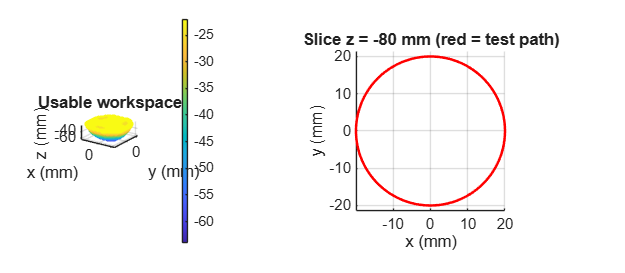

figure('Name','Workspace','Color','w','Position',[50 50 1100 480]);

% Graph 
subplot(1,2,1);
scatter3(WS(:,1),WS(:,2),WS(:,3),6,WS(:,3),'filled');
axis equal; grid on; view(35,20);
xlabel('x (mm)'); ylabel('y (mm)'); zlabel('z (mm)');
title('Usable workspace'); colorbar;
% Graph of Workspace
subplot(1,2,2);
sl = abs(WS(:,3)+80) < stp/2;
plot(WS(sl,1),WS(sl,2),'b.','MarkerSize',6);
hold on; axis equal; grid on;
% Graph of z = -80 mm
tt = linspace(0,2*pi,100);
plot(20*cos(tt),20*sin(tt),'r-','LineWidth',1.5);
xlabel('x (mm)'); ylabel('y (mm)');
title('Slice z = -80 mm (red = test path)');

## Synthesis

% Connecting Link
lList = 60:5:120; % l = 60 - 120 mm (13 round)
vList = zeros(size(lList));

for q = 1:length(lList)
    Pq = P;
    Pq.l = lList(q);
    [~, vList(q)] = workspace_scan(Pq, -60:6:60, -60:6:60, -150:6:-10, 6);
end
% Find width of kinematics 
widthA4 = 2*(P.R + P.L)*cosd(30); % W = 2*(R + L)*cos(30) check size of arms are fully extended fit within A4
fprintf('Total width approx = %.1f mm ', widthA4); % A4 Width = 210 mm

Total width approx = 229.5 mm 

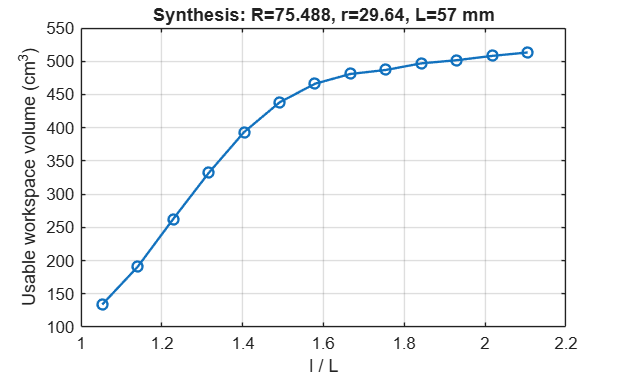

% Plot graph Design synthesis
figure('Name','Synthesis','Color','w');
plot(lList/P.L, vList/1000, 'o-', 'LineWidth', 1.4);
grid on; xlabel('l / L'); ylabel('Usable workspace volume (cm^3)');
title(sprintf('Synthesis: R=%g, r=%g, L=%g mm', P.R, P.r, P.L));

## Trajectory: p, v, a, torque

% Create trajectory
T  = 8;   fps = 30;   % Set 8 second trajectory sampled at 30 frames
N = T*fps + 1;
t  = linspace(0,T,N).';   
dt = t(2)-t(1);
Rc = 20;  z0 = -80;  zA = 8; % Set trajectory parameter: 20 mm circle radius -80 mm and vertical wave amplitude 8 mm
pth = [Rc*cos(2*pi*t/T), Rc*sin(2*pi*t/T), z0 + zA*sin(2*pi*t/(T/2))]; % x = Rcos(ωt), y = Rsin(ωt), z = z0 + zAsin(2ωt)
% Calculate Inverse Kinematics
ink = zeros(N,3);
for kk = 1:N
    ink(kk,:) = ik_num(pth(kk,:).', P).';
end
assert(~any(isnan(ink(:))), 'Trajectory leaves the workspace');
THdeg = rad2deg(ink); % Converts joint angles to degrees 
fprintf('Servo range used: %.1f .. %.1f deg (limit %d..%d)\n', min(THdeg(:)), max(THdeg(:)), P.thLim); % Min and max angles used compared to servo limit

Servo range used: -11.7 .. 9.4 deg (limit 15..170)


% Calculate Velocity and Acceleration
Av  = gradient(ink ,dt); % Velocity
Ava = gradient(Av,dt); % Acceleration
V = zeros(N,3); Ava = zeros(N,3); TAU = zeros(N,3);
Jc = zeros(N,1); gvec = [0;0;-P.g];
for kk = 1:N
    Jn = jac_num(pth(kk,:).',ink(kk,:).',P);
    V(kk,:) = (Jn*Av(kk,:).').';
    Jc(kk) = cond(Jn);
end
Ava = gradient(V,dt); % p_ddot = J*(th_ddot) + Jdot*(th_dot) 
% Jacobian
Jall = zeros(3,3,N);
for kk = 1:N
    Jn = jac_num(pth(kk,:).',ink(kk,:).',P);
    Jall(:,:,kk) = Jn;
    V(kk,:) = (Jn*Av(kk,:).').';
    Jc(kk) = cond(Jn);
end
Ava = gradient(V,dt);
for kk = 1:N
    Jn = Jall(:,:,kk);
    Fneed = P.m*(Ava(kk,:).'*1e-3 - gvec);
    TAU(kk,:) = (Jn.'*Fneed).';
end 
% Examine value
Vref = gradient(pth,dt); % Check Jacobian derived velocity and numerical differentiation of the path
fprintf('Velocity check  max|J*thdot - dp/dt| = %.3f mm/s\n', max(vecnorm(V-Vref,2,2)));

Velocity check  max|J*thdot - dp/dt| = 3484.253 mm/s


fprintf('Max torque = %.1f N.mm (%.2f kg.cm), %.1f %% of stall\n', max(abs(TAU(:))), max(abs(TAU(:)))/98.07, 100*max(abs(TAU(:)))/tauStall);

Max torque = 38.4 N.mm (0.39 kg.cm), 3.6 % of stall


fprintf('Max cond(J) = %.2f (The closer infinity, the closer to a singularity)\n', max(Jc));

Max cond(J) = 1.46 (The closer infinity, the closer to a singularity)


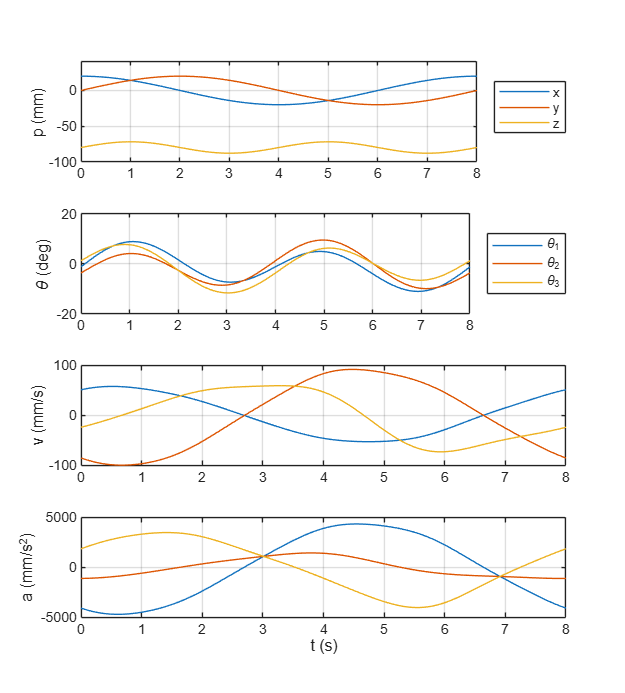

% Plot kinematics 
% plot p(mm) Give blue -> x, red -> y, yellow -> z
figure('Name','Kinematics','Color','w','Position',[80 80 900 1000]);
subplot(4,1,1); plot(t,pth); ylabel('p (mm)'); ylim([-100 40]);
legend('x','y','z','Location','eastoutside'); grid on; subplot(4,1,2);
% plot θ
plot(t,THdeg); ylim([-20 20]);
ylabel('\theta (deg)'); legend('\theta_1','\theta_2','\theta_3','Location','eastoutside');
grid on; subplot(4,1,3);
% plot V (mm/s)
plot(t,V); ylabel('v (mm/s)'); grid on;
subplot(4,1,4);
% plot a (mm/s^2)
plot(t,Ava); 
ylabel('a (mm/s^2)'); xlabel('t (s)'); grid on;

% Export to simscape model
save('delta_trajectory.mat','t','pth','ink','THdeg','V','Ava','TAU','P');


## Animation

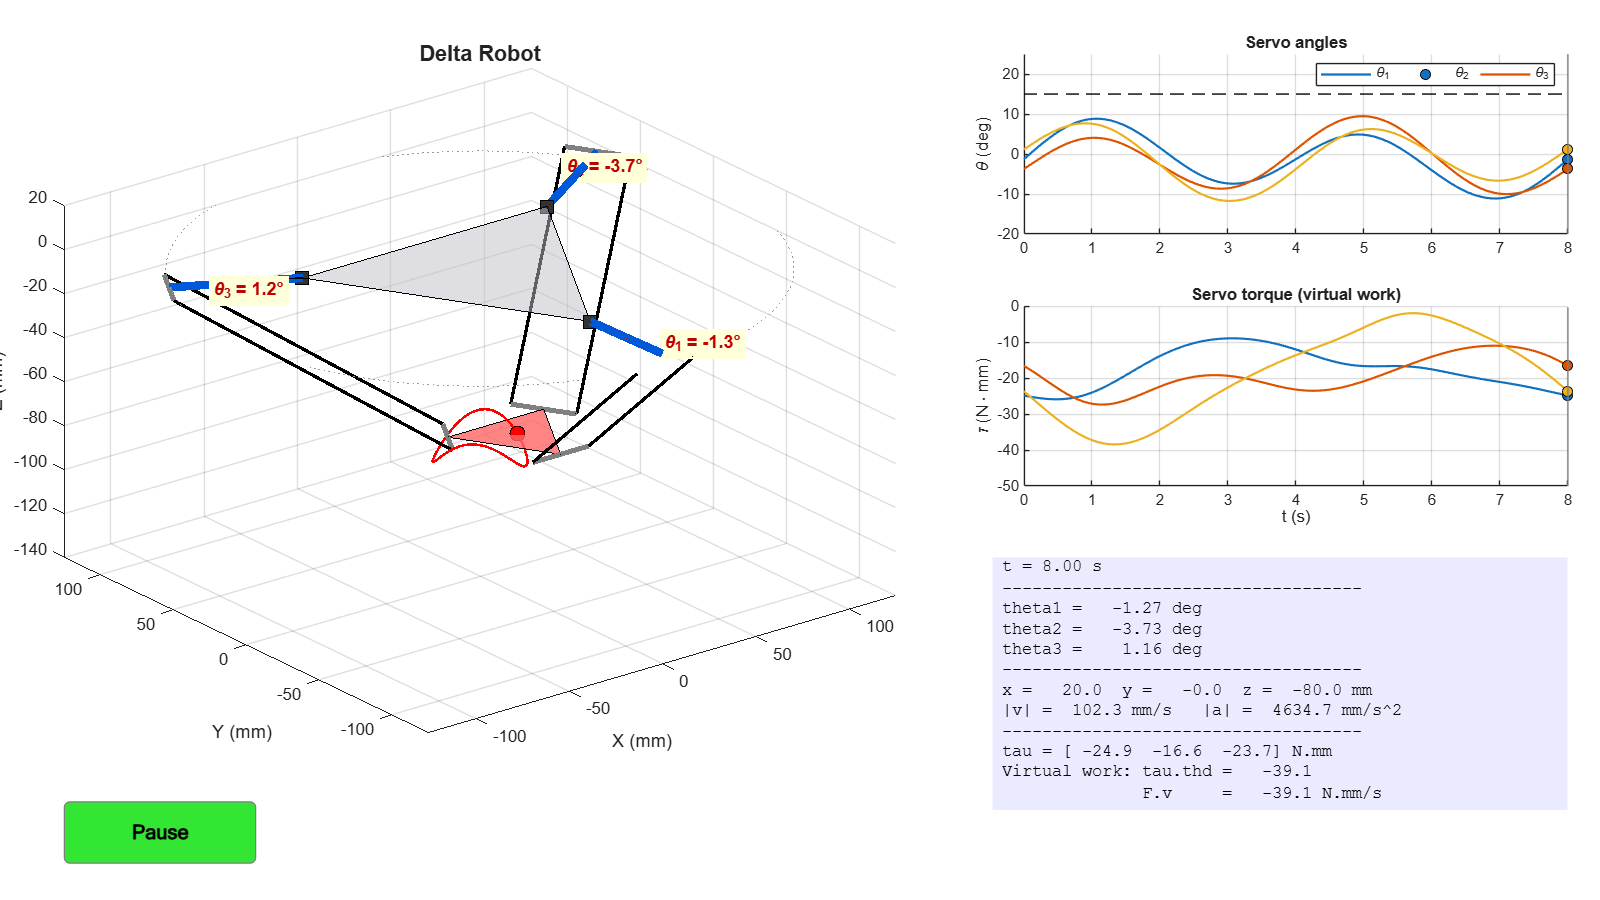

% Create GUT
fig = figure('Name','Delta Robot','Color','w','Position',[60 60 1280 720], 'MenuBar','none','ToolBar','none','Resize','off');

% 3D robot
ax3 = axes('Parent',fig,'Position',[0.04 0.17 0.52 0.77]); % 3D view point
H   = make_robot(ax3,P);
title(ax3,'Delta Robot','FontSize',13);

% Servo Angle plot
axTh = axes('Parent',fig,'Position',[0.64 0.74 0.34 0.20]); % Create the top right live plot of servo angles  
hold(axTh,'on'); grid(axTh,'on');
cols = lines(3);
hDot = gobjects(1,3);
for i = 1:3 
    plot(axTh,t,THdeg(:,i),'Color',cols(i,:),'LineWidth',1.3); 
    hDot(i) = plot(axTh,t(1),THdeg(1,i),'o', 'MarkerFaceColor',cols(i,:), 'MarkerEdgeColor','k');
end
plot(axTh,[0 T],[P.thLim(1) P.thLim(1)],'k--'); 
plot(axTh,[0 T],[P.thLim(2) P.thLim(2)],'k--');
hCur = plot(axTh,[0 0],[-20 25],'Color',[.5 .5 .5]);
ylim(axTh,[-20 25]); 
xlim(axTh,[0 T]); ylabel(axTh,'\theta (deg)'); title(axTh,'Servo angles');
legend(axTh,{'\theta_1','\theta_2','\theta_3'},'Location','northeast','Orientation','horizontal');

% Servo Torque plot
axTa = axes('Parent',fig,'Position',[0.64 0.46 0.34 0.20]); 
hold(axTa,'on'); grid(axTa,'on');
hDot2 = gobjects(1,3);
for i = 1:3
    plot(axTa,t,TAU(:,i),'Color',cols(i,:),'LineWidth',1.3);
    hDot2(i) = plot(axTa,t(1),TAU(1,i),'o', 'MarkerFaceColor',cols(i,:), 'MarkerEdgeColor','k');
end
xlim(axTa,[0 T]); ylabel(axTa,'\tau (N\cdotmm)'); xlabel(axTa,'t (s)'); 
title(axTa,'Servo torque (virtual work)');
hCur2 = plot(axTa,[0 0],[min(TAU(:))*1.3 max(TAU(:))*0.7+1],'Color',[.5 .5 .5]);

% Information Display
hInfo = uicontrol('Style','text','Units','normalized','Position',[0.62 0.10 0.36 0.28], ...
    'BackgroundColor',[0.92 0.92 1],'HorizontalAlignment','left','FontName','FixedWidth','FontSize',10); % Create text box in bottom right
% Pause button
btn = uicontrol('Style','togglebutton','String','Pause','Units','normalized', ...
    'Position',[0.04 0.04 0.12 0.07],'FontSize',12,'FontWeight','bold', ...
    'BackgroundColor',[0.2 0.9 0.2],'Callback',@pause_cb);

% Video record
if recordVideo
    vw = VideoWriter(aviName,'Motion JPEG AVI');  
    vw.FrameRate = fps;  
    vw.Quality = 95;  
    open(vw);
end

% Animation loop
for kk = 1:N
    while ishandle(fig) && get(btn,'Value')==1 
        pause(0.05); 
    end
    if ~ishandle(fig)
        break; 
    end
    % update robot position
    update_robot(H,pth(kk,:).',ink(kk,:).',pth(1:kk,:),P);
    % update time
    set([hCur hCur2],'XData',[t(kk) t(kk)]);
    % update servo angle marker
    for i = 1:3
        set(hDot(i),'XData',t(kk),'YData',THdeg(kk,i)); 
    end
    % update servo torque marker
    for i = 1:3
        set(hDot2(i),'XData',t(kk),'YData',TAU(kk,i)); 
    end
    % Instantaneous power
    Pin  = TAU(kk,:)*Av(kk,:).';                                   
    Fn   = P.m*(Ava(kk,:).'*1e-3 - gvec);   
    Pout = Fn.'*V(kk,:).';   
    
    % Display Information 
    hInfo.String = {
    sprintf(' t = %.2f s',t(kk))
    ' ------------------------------------'
    sprintf(' theta1 = %7.2f deg',THdeg(kk,1))
    sprintf(' theta2 = %7.2f deg',THdeg(kk,2))
    sprintf(' theta3 = %7.2f deg',THdeg(kk,3))
    ' ------------------------------------'
    sprintf(' x = %6.1f  y = %6.1f  z = %6.1f mm',pth(kk,:))
    sprintf(' |v| = %6.1f mm/s   |a| = %7.1f mm/s^2', ...
        norm(V(kk,:)),norm(Ava(kk,:)))
    ' ------------------------------------'
    sprintf(' tau = [%6.1f %6.1f %6.1f] N.mm',TAU(kk,:))
    sprintf(' Virtual work: tau.thd = %7.1f',Pin)
    sprintf('               F.v     = %7.1f N.mm/s',Pout)};

    drawnow;
    if recordVideo
        writeVideo(vw,getframe(fig)); 
    end
end

% Closed video
if recordVideo
    close(vw); 
    fprintf('Saved %s\n',aviName); 
end

Saved delta_robot_motion.avi


## Function

% Re check
function th = ik_num(p,P) % closed-form inverse kinematics 
    d = P.R - P.r;   th = nan(3,1);
    for i = 1:3
        w = p(1)*cos(P.phi(i)) + p(2)*sin(P.phi(i));
        E = 2*P.L*(d-w);   F = 2*P.L*p(3);
        wt = -p(1)*sin(P.phi(i)) + p(2)*cos(P.phi(i));
        G = (w-d)^2 + (wt+P.ds)^2 + p(3)^2 + P.L^2 - P.l^2;
        D = E^2 + F^2 - G^2;
    if D < 0, th(:) = NaN; 
        return; 
    end
    th(i) = 2*atan2(-F + P.sg*sqrt(D), G - E); % Calculate joint angle 
    end
    th = mod(th,2*pi) - pi; % [0, 360]
end
 
function p = fk_num(th,P) % forward kinematics : platform below base
    d = P.R - P.r;   c = zeros(3,3);
    for i = 1:3
        u = [cos(P.phi(i)); sin(P.phi(i)); 0];   tg = [-sin(P.phi(i)); cos(P.phi(i)); 0];
        c(:,i) = (d + P.L*cos(th(i)))*u + [0;0;-P.L*sin(th(i))] - P.ds*tg;
    end
    e  = c(:,2)-c(:,1);   dd = norm(e);   ex = e/dd; % Trilateration by constructing a local orthonormal a coordinate frame (ex,ey,ez) at c1, c2, and c3
    v  = c(:,3)-c(:,1);   i1 = ex.'*v;    ey = v - i1*ex;   ey = ey/norm(ey);   ez = cross(ex,ey);
    j1 = ey.'*v;
    x  = dd/2;   y = (i1^2 + j1^2)/(2*j1) - i1*x/j1; % Solve intersection coordinates of three sphere in that local frame
    zz = P.l^2 - x^2 - y^2;
    if zz < 0
        p = nan(3,1); 
        return; 
    end
        q = sqrt(zz)*ez;   
        if q(3) > 0
            q = -q; 
        end
        p = c(:,1) + x*ex + y*ey + q; % Transforms the intersection point to global base coordinates
    end
 
function [J,dJx,dJth] = jac_num(p,th,P) % pdot = J*thdot
    d = P.R - P.r;   Jx = zeros(3);   Jt = zeros(3);   k = [0;0;1];
    for i = 1:3
        u  = [cos(P.phi(i)); sin(P.phi(i)); 0];
        tg = [-sin(P.phi(i)); cos(P.phi(i)); 0];
        c  = (d + P.L*cos(th(i)))*u - P.L*sin(th(i))*k - P.ds*tg;
        dc = P.L*(-sin(th(i))*u - cos(th(i))*k);
        s  = p - c;   Jx(i,:) = s.';   Jt(i,i) = s.'*dc;
    end
    J = Jx\Jt;   dJx = det(Jx);   dJth = det(Jt);
end
 
function [wsp,vol] = workspace_scan(P,xs,ys,zs,stp) % points reachable with servo limits and away from singularities
    lo = deg2rad(P.thLim(1));   hi = deg2rad(P.thLim(2));
    wsp = zeros(0,3);
    for xi = xs
        for yi = ys
            for zi = zs
                t = ik_num([xi;yi;zi],P);
                if ~any(isnan(t)) && all(t>=lo) && all(t<=hi)
                    if rcond(jac_num([xi;yi;zi],t,P)) > 1e-3
                        wsp(end+1,:) = [xi yi zi]; 
                    end
                end
            end
        end
    end
    vol = size(wsp,1)*stp^3;      
end

% Create Link of Delta Robot
function H = make_robot(ax,P)
    hold(ax,'on'); grid(ax,'on'); axis(ax,'equal');
    set(ax,'XLim',[-125 125],'YLim',[-125 125],'ZLim',[-140 20]);
    view(ax,-38,22);   xlabel(ax,'X (mm)'); ylabel(ax,'Y (mm)'); zlabel(ax,'Z (mm)');
    B = zeros(3,3);
    for i = 1:3
        B(:,i) = P.R*[cos(P.phi(i)); sin(P.phi(i)); 0]; 
    end
    patch(ax,'XData',B(1,:),'YData',B(2,:),'ZData',B(3,:),'FaceColor',[.75 .75 .78],'FaceAlpha',.5,'EdgeColor','k');
    th = linspace(0,2*pi,100);
    plot3(ax,(P.R+P.L)*cos(th),(P.R+P.L)*sin(th),zeros(size(th)),':','Color',[.6 .6 .6]);   % reach circle of arms
    plot3(ax,B(1,:),B(2,:),B(3,:),'s','MarkerSize',10,'MarkerFaceColor',[.2 .2 .2],'MarkerEdgeColor','k');
    for i = 1:3
        H.arm(i)  = plot3(ax,nan,nan,nan,'-','Color',[0.0 0.35 0.85],'LineWidth',5);
        H.bar(i)  = plot3(ax,nan,nan,nan,'-','Color',[.5 .5 .5],'LineWidth',3);
        H.rodA(i) = plot3(ax,nan,nan,nan,'-','Color','k','LineWidth',2);
        H.rodB(i) = plot3(ax,nan,nan,nan,'-','Color','k','LineWidth',2);
        H.pbar(i) = plot3(ax,nan,nan,nan,'-','Color',[.5 .5 .5],'LineWidth',3);
        H.ref(i)  = plot3(ax,nan,nan,nan,'k--','LineWidth',1);
        H.arc(i)  = plot3(ax,nan,nan,nan,'-','Color',[0.85 0.1 0.1],'LineWidth',2);
        H.txt(i)  = text(ax,0,0,0,'','FontSize',11,'FontWeight','bold','Color',[0.75 0 0],'Interpreter','tex', ...
                     'BackgroundColor',[1 1 .85],'Margin',2);
    end
    H.plat  = patch(ax,'XData',[0 0 0],'YData',[0 0 0],'ZData',[0 0 0],'FaceColor',[1 .4 .4],'FaceAlpha',.8,'EdgeColor','k');
    H.trail = plot3(ax,nan,nan,nan,'r-','LineWidth',1.5);
    H.ee    = plot3(ax,nan,nan,nan,'o','MarkerSize',9,'MarkerFaceColor','r','MarkerEdgeColor','k');
end
 
function update_robot(H,p,th,trail,P)
    k = [0;0;1];   rho = 0.45*P.L;   Pl = zeros(3,3);
    for i = 1:3
        ph = P.phi(i);   
        u = [cos(ph); sin(ph); 0];   
        t = [-sin(ph); cos(ph); 0];
        B  = P.R*u;
        E  = (P.R + P.L*cos(th(i)))*u - P.L*sin(th(i))*k; % elbow
        Pi = p + P.r*u + P.ds*t; % center at platform
        Pl(:,i) = Pi;
        seg(H.arm(i), B, E);
        seg(H.bar(i), E-P.hT*t, E+P.hT*t);
        seg(H.rodA(i), E+P.hT*t, Pi+P.hB*t);
        seg(H.rodB(i), E-P.hT*t, Pi-P.hB*t);
        seg(H.pbar(i), Pi-P.hB*t, Pi+P.hB*t);
        seg(H.ref(i), B, B+1.5*rho*u); % horizontal reference (theta = 0)
        s = linspace(0,th(i),25);
        a = B + rho*(u*cos(s) - k*sin(s));
        set(H.arc(i),'XData',a(1,:),'YData',a(2,:),'ZData',a(3,:));
        m = B + 1.55*rho*(u*cos(th(i)/2) - k*sin(th(i)/2)) + 8*t;
        set(H.txt(i),'Position',m.','String',sprintf('\\theta_%d = %.1f%c',i,rad2deg(th(i)),char(176)));
    end
    set(H.plat,'XData',Pl(1,:),'YData',Pl(2,:),'ZData',Pl(3,:));
    set(H.trail,'XData',trail(:,1),'YData',trail(:,2),'ZData',trail(:,3));
    set(H.ee,'XData',p(1),'YData',p(2),'ZData',p(3));
end
 
function seg(h,a,b)
    set(h,'XData',[a(1) b(1)],'YData',[a(2) b(2)],'ZData',[a(3) b(3)]);
end
 
function pause_cb(src,~)
    if get(src,'Value')==1
        set(src,'String','Resume','BackgroundColor',[1 0.8 0.2]);
    else
        set(src,'String','Pause','BackgroundColor',[0.2 0.9 0.2]);
    end
end